mojave = robot

mojave =   robot with properties:

        lidar: [1×1 serial]
       ir_vec: 'A2A3A4A5A6A7'
    sonar_vec: 'A0A1'
      lsm_obj: []
          neo: []


mojave.lidar_setup();
% mojave.setup(); % can't run yet because not plugged into arduino 
% mojave.lidar_setup(); % can't run yet because not plugged into lidar 

% Camera test
mojave.setup_USB_camera();
img = mojave.sense_cam();
mojave.robot_cam
imshow(img)

LaserPlot1 = struct with fields:
    figure: [1×1 Figure]


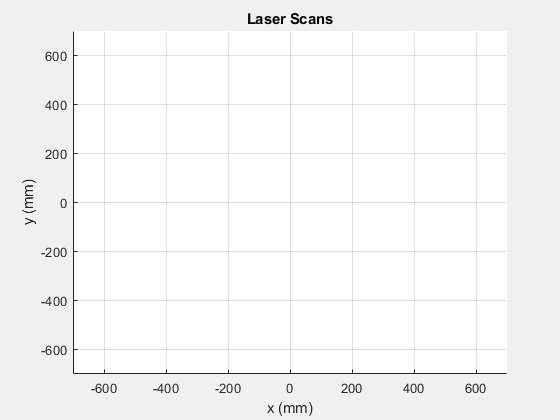

Laser scan figure set


% LiDAR initialize figure test
mojave.initialize_lidar_display();

%fopen(mojave.lidar)
% set(mojave.lidar, "Timeout", 3);
% set(mojave.lidar, "InputBufferSize", 20000);
% set(mojave.lidar, "Terminator", "LF");

mojave.lidar_scan();

Index exceeds the number of array elements. Index must not exceed 1.

Error in FunRoboLidarScan (line 26)
rangedata=data(i(3)+1:end-1);

Error in robot/lidar_scan (line 70)
                [A] = FunRoboLidarScan(obj.lidar);              % actual lidar scan range data sored in [A]

fclose(mojave.lidar);